# Lab 1

## Es 1

n = 100;
alpha = 4;
e = ones(n,1);
A = spdiags([-e alpha*e -e], -1:1, n, n);
A = full(A);
kA = norm(A)*norm(inv(A))

kA =    2.998066064646729


b = A*e;

## Es 2

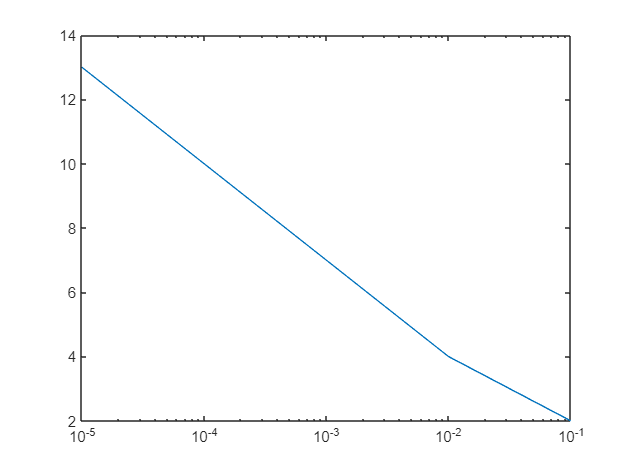

format long
s = 5;
k = zeros(s, 1);
tol = zeros(s, 1);
for q = 1:s
    tol(q) = 10^-q;
    x = zeros(n, 1);
    r = b - A*x;
    k(q) = 0;
    while norm(r)/norm(b) > tol(q)
        k(q) = k(q) + 1;
        z = A*r;
        alphaK = r'*r/(r'*z);
        x = x + alphaK*r;
        r = r - alphaK*z;
    end
end
semilogx(tol, k)

## Es 3

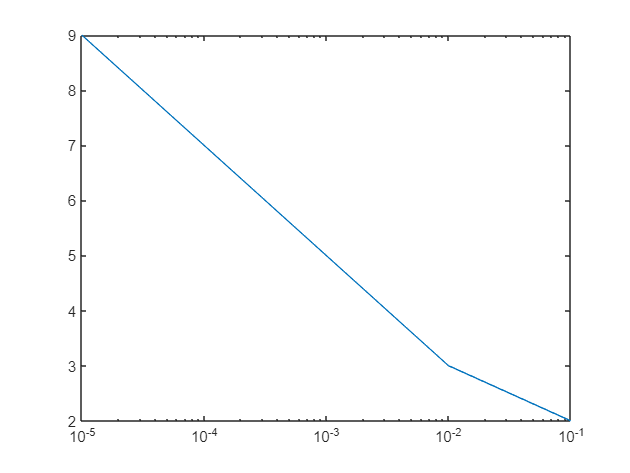

format long
s = 5;
k = zeros(s, 1);
tol = zeros(s, 1);
for q = 1:s
    tol(q) = 10^-q;
    [x, flag, res, iter] = pcg(A, b, tol(q));
    k(q) = iter;
end
semilogx(tol, k)